Nahrávání dat a vytvoření proměnných

T = readtable('data.csv', 'HeaderLines', 2);

group1 = T(T.Skupina == 1, :);
group2 = T(T.Skupina == 2, :);
group3 = T(T.Skupina == 3, :);
group4 = T(T.Skupina == 4, :);
group5 = T(T.Skupina == 5, :);
group6 = T(T.Skupina == 6, :);
group7 = T(T.Skupina == 7, :);

colNames = T.Properties.VariableNames

colNames = 1×33 cell array
    {'Inicialy'}    {'EDSS'}    {'Skupina'}    {'vek'}    {'delkaDolni'}    {'NormalniChuze'}    {'RychlaChuze'}    {'NormalniChuze_1'}    {'RychlaChuze_1'}    {'NormalniChuze_2'}    {'RychlaChuze_2'}    {'NormalniChuze_3'}    {'RychlaChuze_3'}    {'NormalniChuze_4'}    {'RychlaChuze_4'}    {'NormalniChuze_5'}    {'RychlaChuze_5'}    {'NormalniChuze_6'}    {'RychlaChuze_6'}    {'NormalniChuze_7'}    {'RychlaChuze_7'}    {'NormalniChuze_8'}    {'RychlaChuze_8'}    {'NormalniChuze_9'}    {'RychlaChuze_9'}    {'NormalniChuze_10'}    {'RychlaChuze_10'}    {'NormalniChuze_11'}    {'RychlaChuze_11'}    {'NormalniChuze_12'}    {'RychlaChuze_12'}    {'NormalniChuze_13'}    {'RychlaChuze_13'}




% Extract velocity data from cell arrays
group1_normal_velocity = group1.NormalniChuze;
group2_normal_velocity = group2.NormalniChuze;
group3_normal_velocity = group3.NormalniChuze;
group4_normal_velocity = group4.NormalniChuze;
group5_normal_velocity = group5.NormalniChuze;
group6_normal_velocity = group6.NormalniChuze;
group7_normal_velocity = group7.NormalniChuze;

% Create the boxplot
all_normal_velocities = [group1_normal_velocity; group2_normal_velocity; group3_normal_velocity; ...
                  group4_normal_velocity; group5_normal_velocity; group6_normal_velocity; ...
                  group7_normal_velocity];

% Create corresponding group labels
normal_group_labels = [ones(length(group1_normal_velocity), 1); ...
                ones(length(group2_normal_velocity), 1)*2; ...
                ones(length(group3_normal_velocity), 1)*3; ...
                ones(length(group4_normal_velocity), 1)*4; ...
                ones(length(group5_normal_velocity), 1)*5; ...
                ones(length(group6_normal_velocity), 1)*6; ...
                ones(length(group7_normal_velocity), 1)*7];

Vykreslení boxplots pro rychlost normální chůze přes 7 skupin

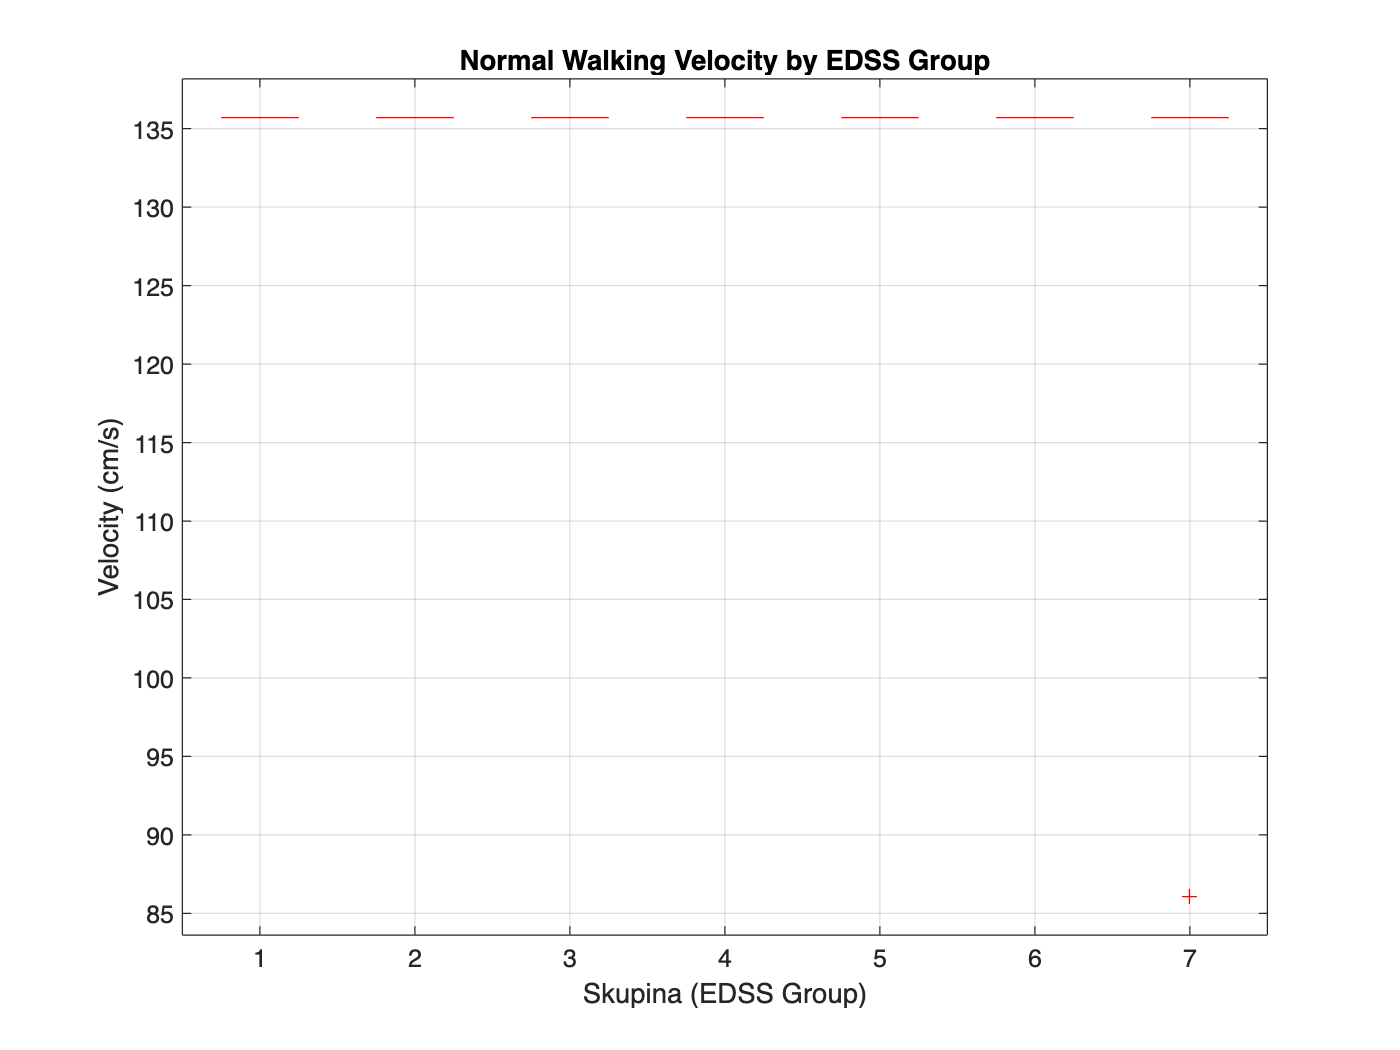

figure();
boxplot(all_normal_velocities, normal_group_labels, 'Labels', {'1','2','3','4','5','6','7'});
title('Normal Walking Velocity by EDSS Group');
xlabel('Skupina (EDSS Group)');
ylabel('Velocity (cm/s)');
grid on;

%graf vypadá divně, ale je to správně všichni měli 135.7 rychlost

Vykreslení rychlosti rychlé chůze přes 7 skupin

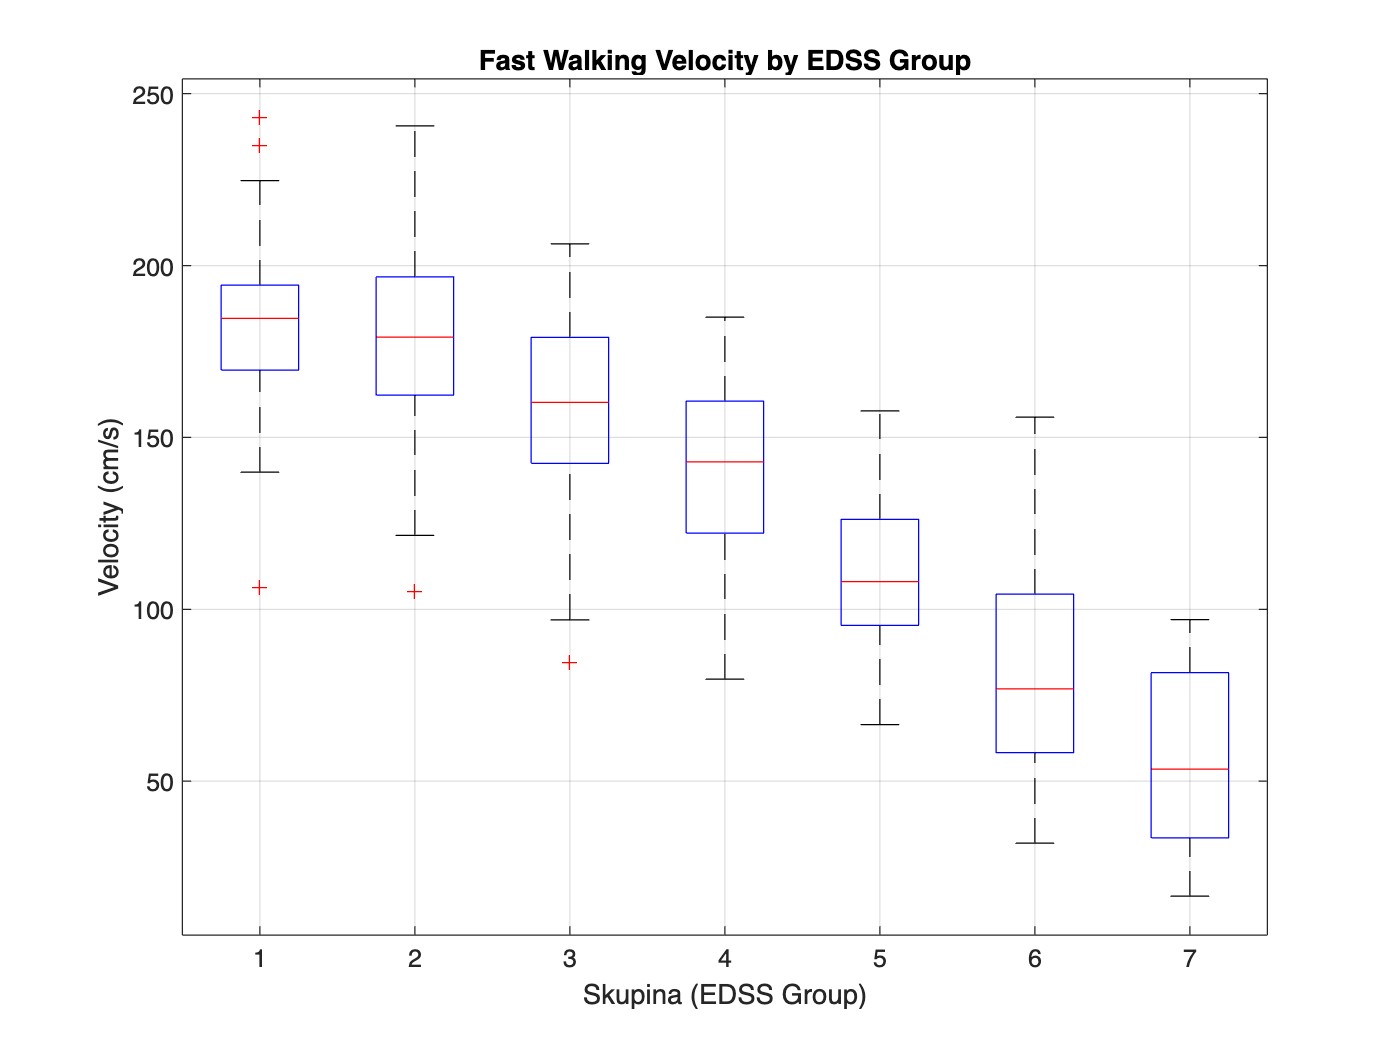

group1_fast_velocity = group1.RychlaChuze;
group2_fast_velocity = group2.RychlaChuze;
group3_fast_velocity = group3.RychlaChuze;
group4_fast_velocity = group4.RychlaChuze;
group5_fast_velocity = group5.RychlaChuze;
group6_fast_velocity = group6.RychlaChuze;
group7_fast_velocity = group7.RychlaChuze;

all_fast_velocities = [group1_fast_velocity; group2_fast_velocity; group3_fast_velocity; ...
                  group4_fast_velocity; group5_fast_velocity; group6_fast_velocity; ...
                  group7_fast_velocity];

% Create corresponding group labels
fast_group_labels = [ones(length(group1_fast_velocity), 1); ...
                ones(length(group2_fast_velocity), 1)*2; ...
                ones(length(group3_fast_velocity), 1)*3; ...
                ones(length(group4_fast_velocity), 1)*4; ...
                ones(length(group5_fast_velocity), 1)*5; ...
                ones(length(group6_fast_velocity), 1)*6; ...
                ones(length(group7_fast_velocity), 1)*7];

figure();
boxplot(all_fast_velocities, fast_group_labels, 'Labels', {'1','2','3','4','5','6','7'});
title('Fast Walking Velocity by EDSS Group');
xlabel('Skupina (EDSS Group)');
ylabel('Velocity (cm/s)');
grid on;

% Nahrávání dat a vytvoření proměnných
T = readtable('data.csv', 'HeaderLines', 2);

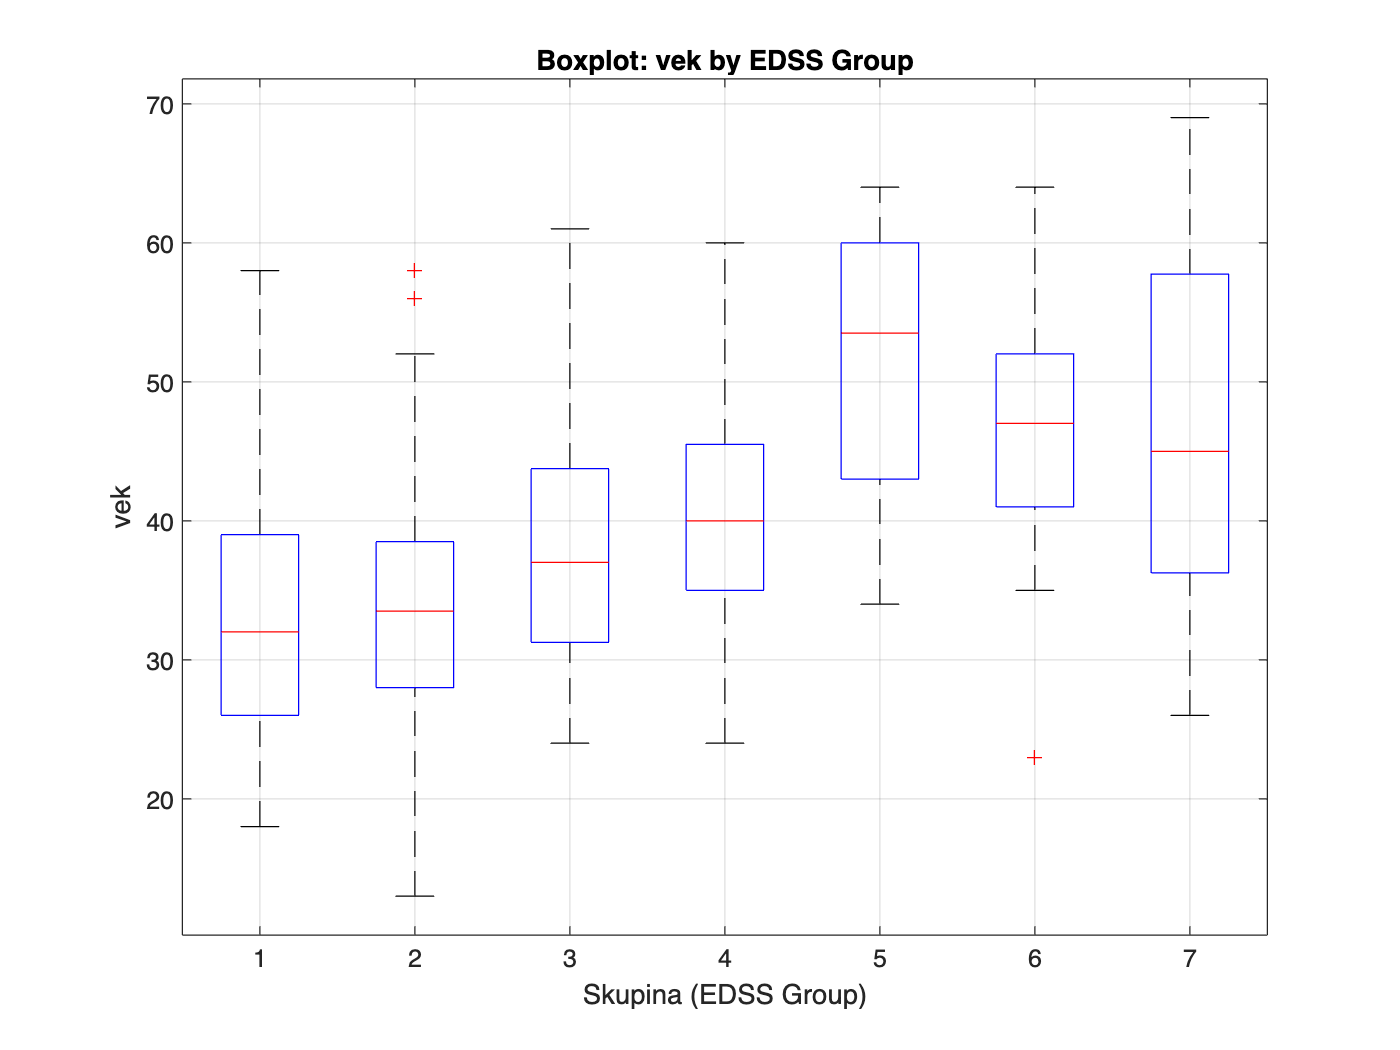

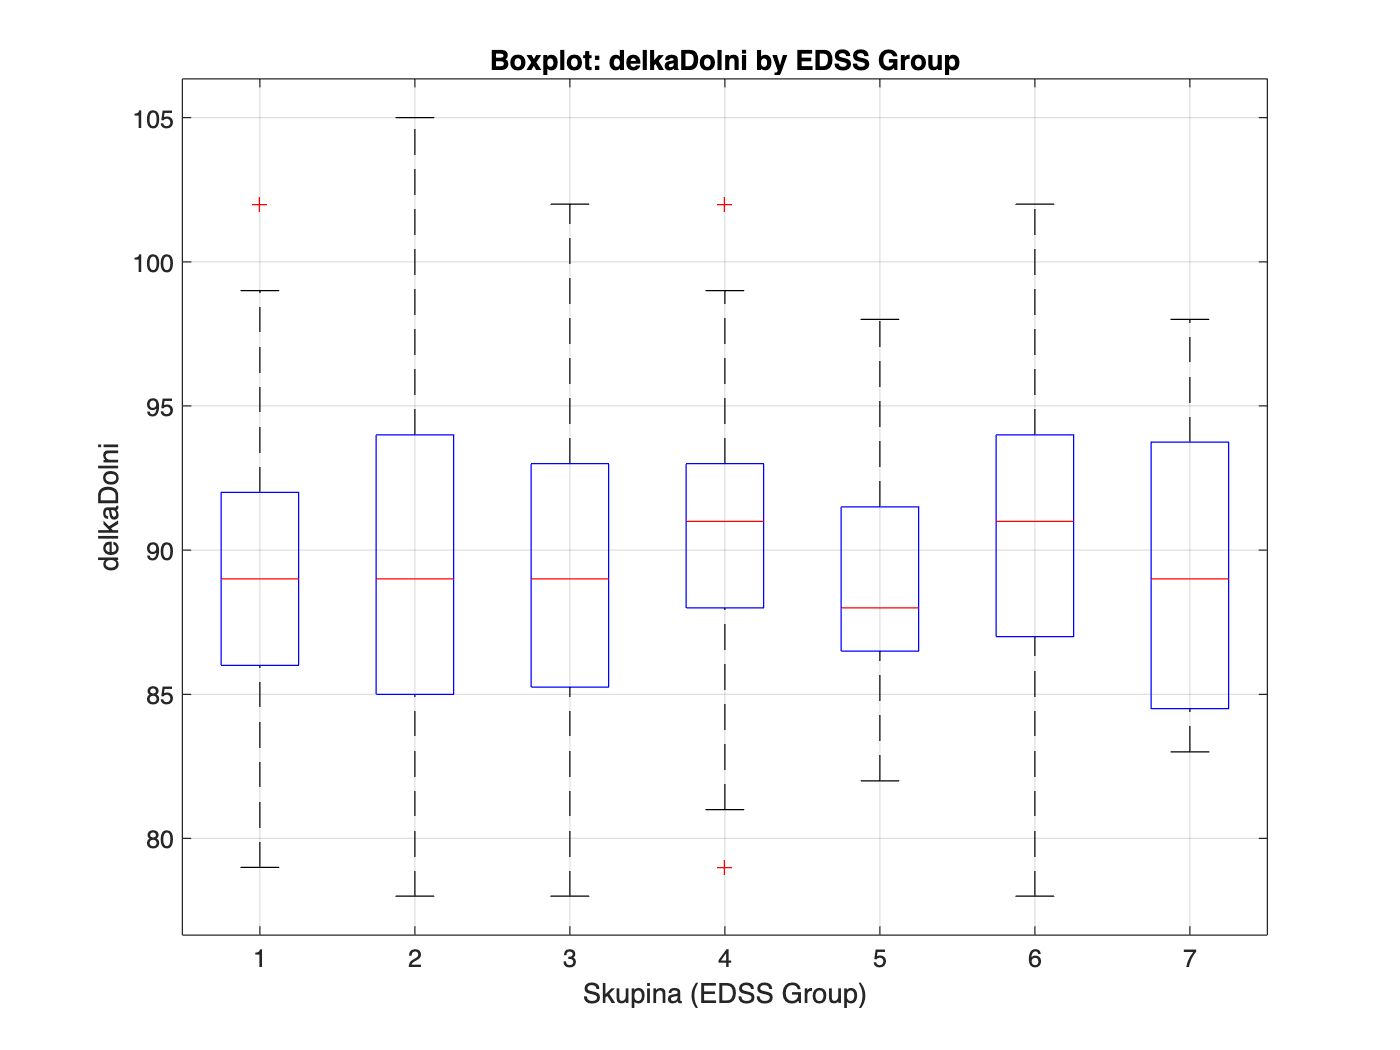

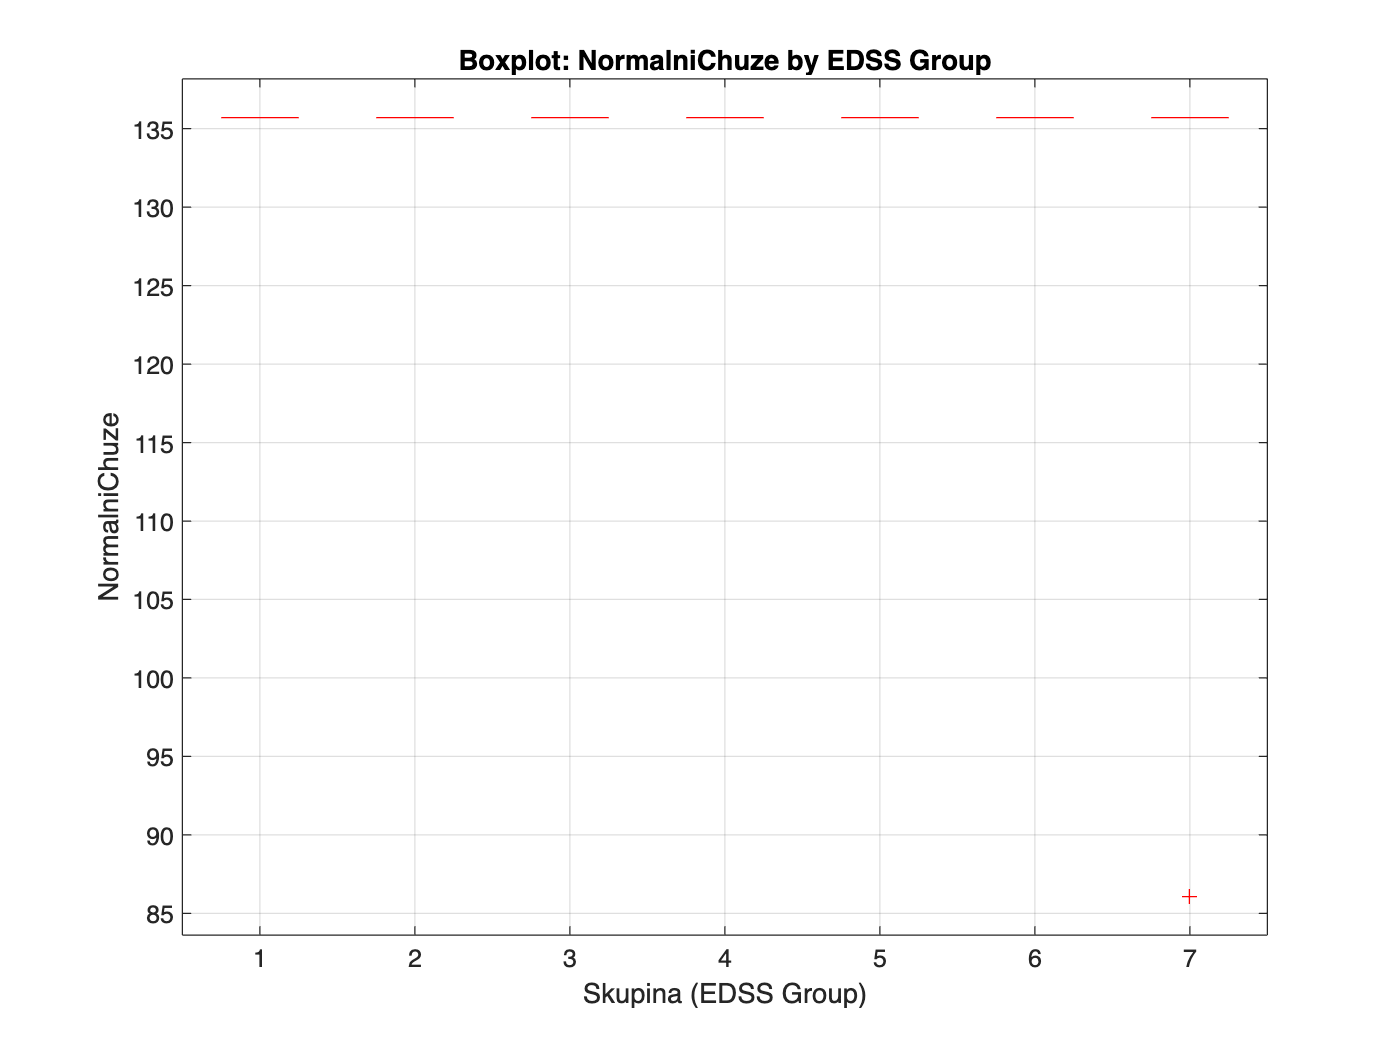

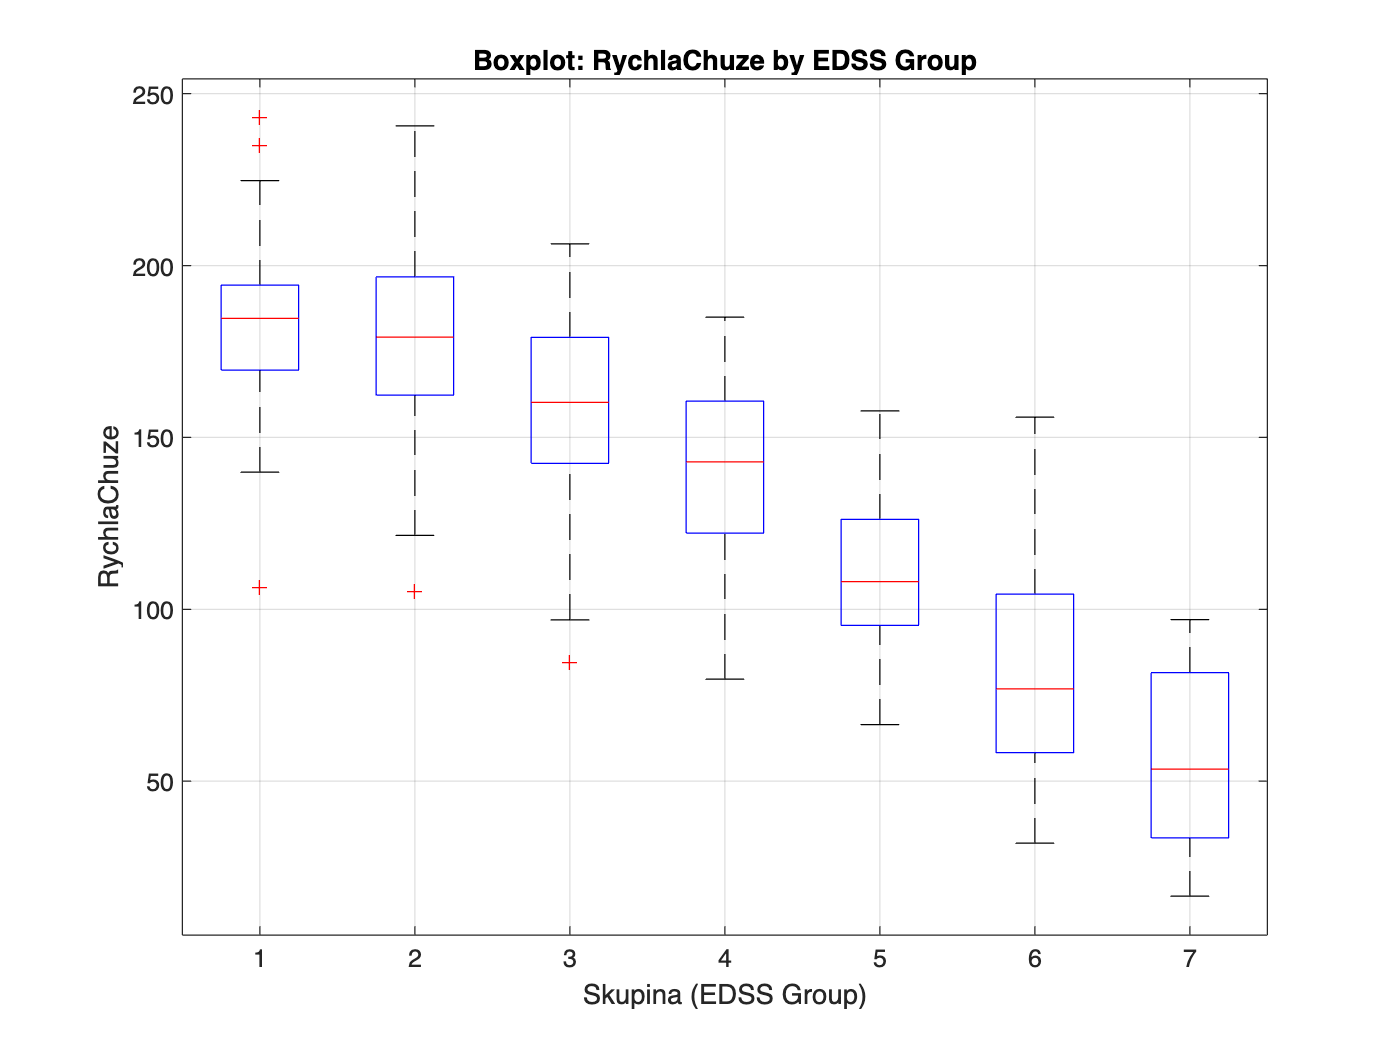

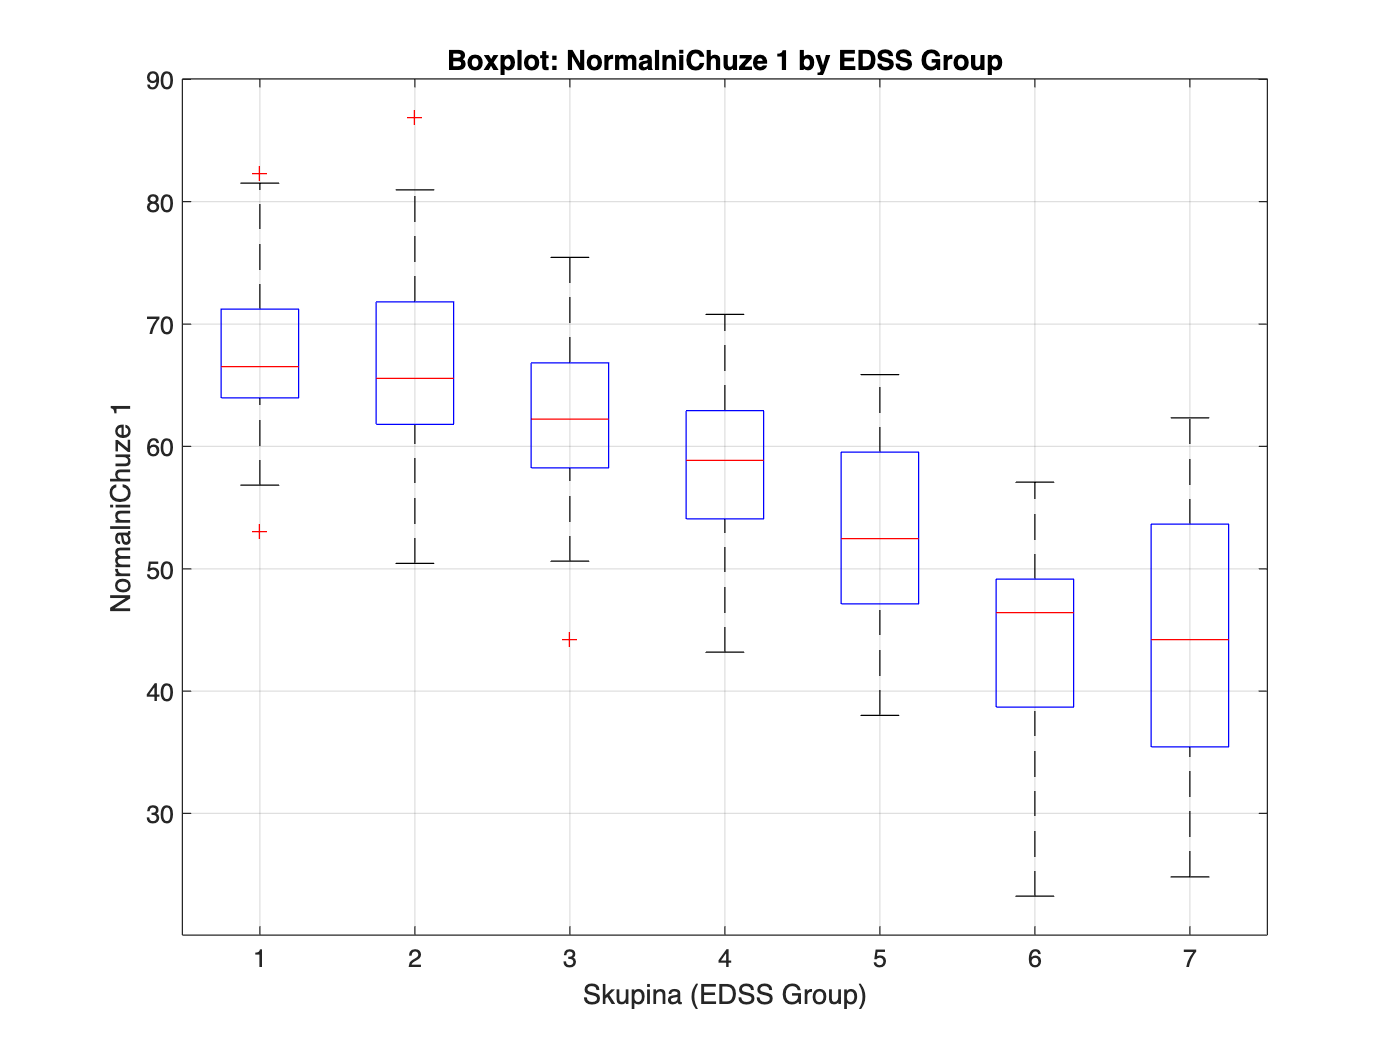

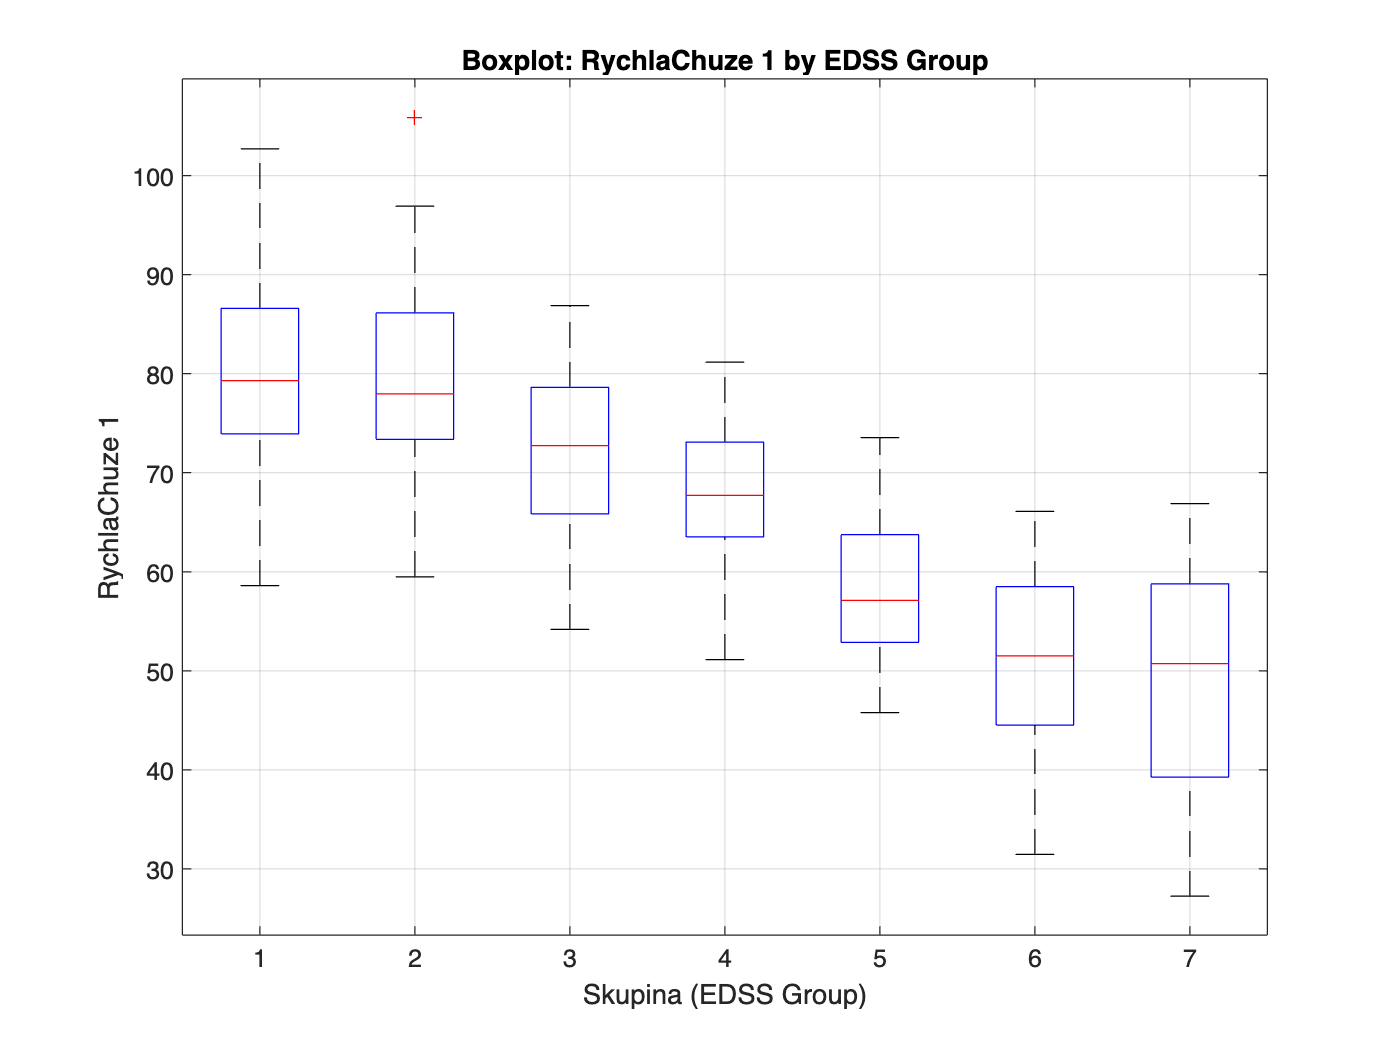

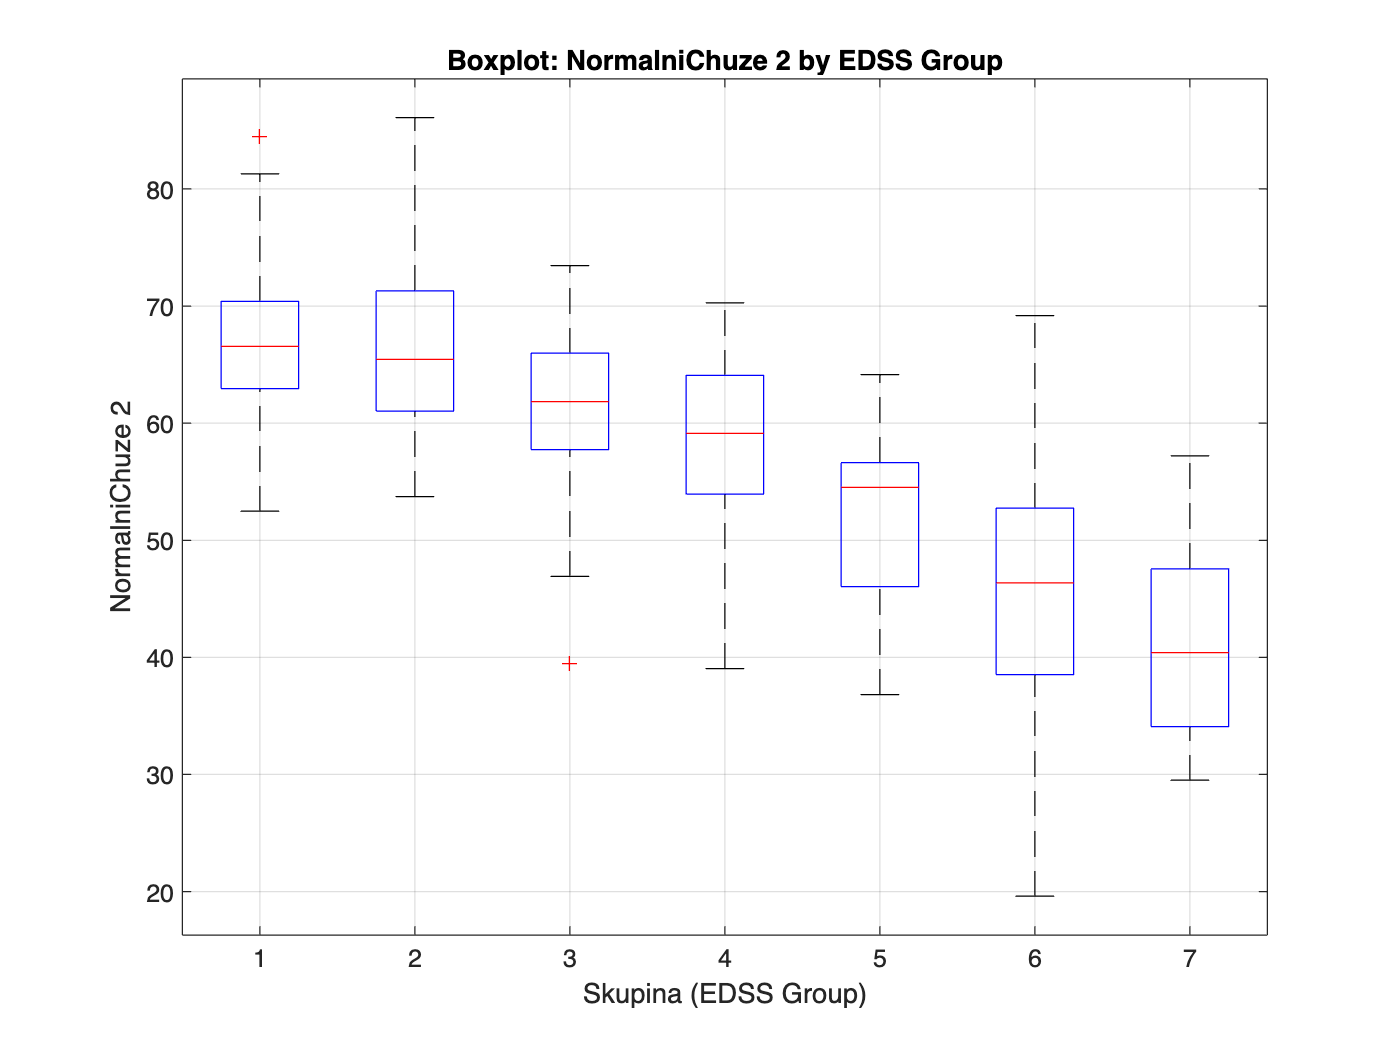

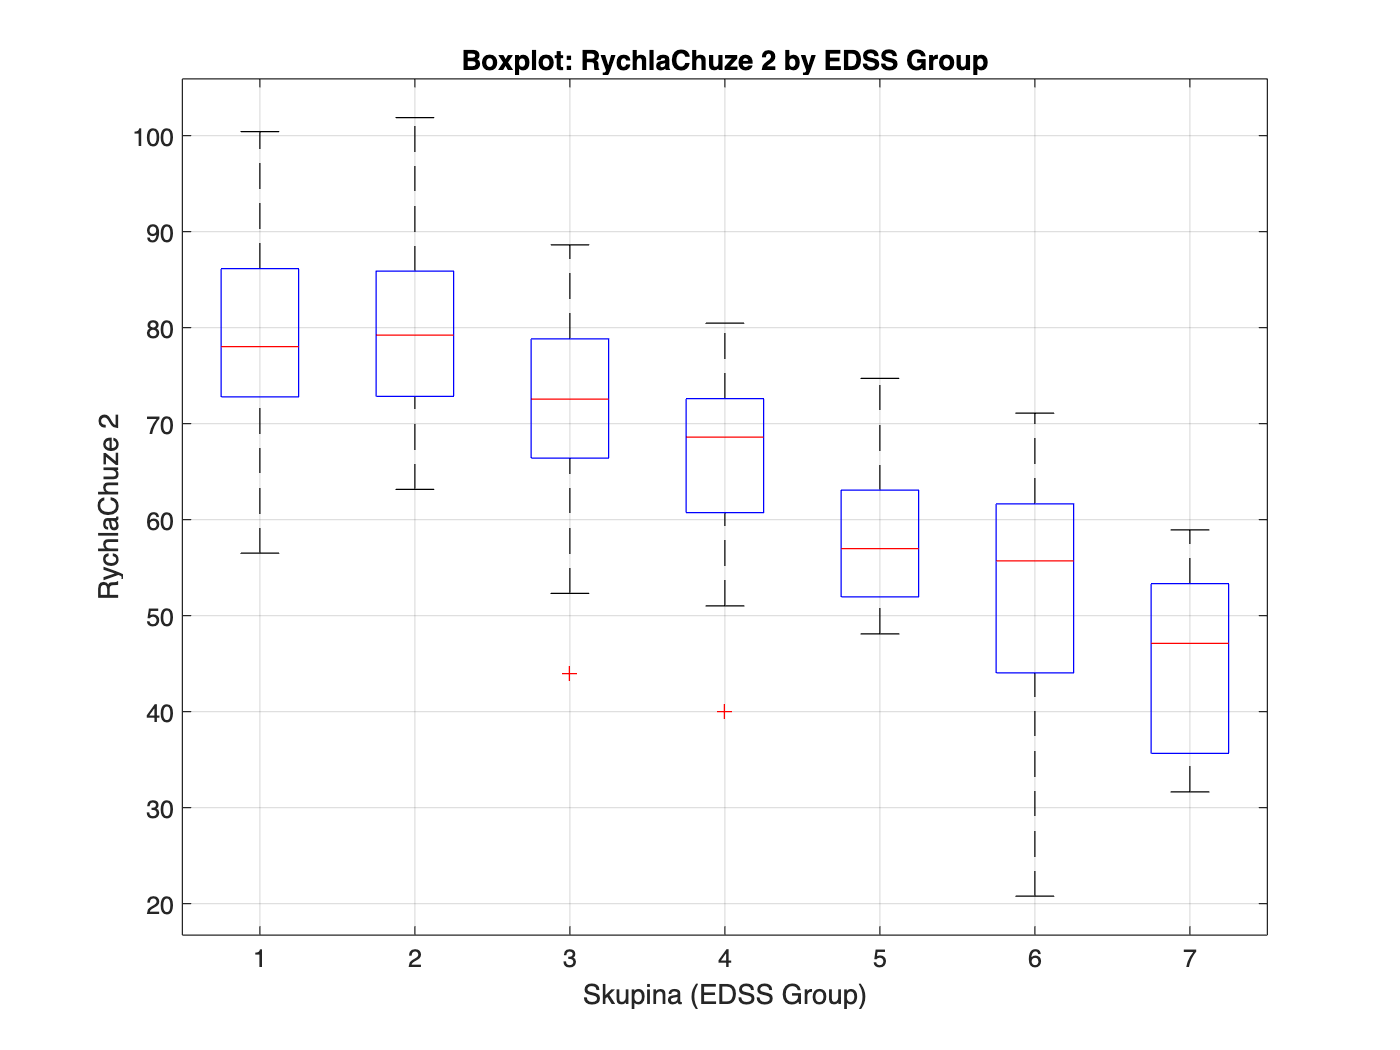


% Rozdělení do skupin podle EDSS
group1 = T(T.Skupina == 1, :);
group2 = T(T.Skupina == 2, :);
group3 = T(T.Skupina == 3, :);
group4 = T(T.Skupina == 4, :);
group5 = T(T.Skupina == 5, :);
group6 = T(T.Skupina == 6, :);
group7 = T(T.Skupina == 7, :);

% Získání názvů sloupců
colNames = T.Properties.VariableNames;

% Výběr pouze numerických sloupců (vyloučení Inicialy, EDSS, Skupina)
numericCols = colNames(4:end); % od 'vek' dál

% Vytvoření boxplotů pro každý sloupec
for i = 1:length(numericCols)
    colName = numericCols{i};
    
    % Extrakce dat pro aktuální sloupec ze všech skupin
    group1_data = group1.(colName);
    group2_data = group2.(colName);
    group3_data = group3.(colName);
    group4_data = group4.(colName);
    group5_data = group5.(colName);
    group6_data = group6.(colName);
    group7_data = group7.(colName);
    
    % Spojení všech dat
    all_data = [group1_data; group2_data; group3_data; ...
                group4_data; group5_data; group6_data; ...
                group7_data];
    
    % Vytvoření skupinových labelů
    group_labels = [ones(length(group1_data), 1); ...
                    ones(length(group2_data), 1)*2; ...
                    ones(length(group3_data), 1)*3; ...
                    ones(length(group4_data), 1)*4; ...
                    ones(length(group5_data), 1)*5; ...
                    ones(length(group6_data), 1)*6; ...
                    ones(length(group7_data), 1)*7];
    
    % Vytvoření boxplotu
    figure();
    boxplot(all_data, group_labels, 'Labels', {'1','2','3','4','5','6','7'});
    title(['Boxplot: ', strrep(colName, '_', ' '), ' by EDSS Group']);
    xlabel('Skupina (EDSS Group)');
    ylabel(strrep(colName, '_', ' '));
    grid on;
    
    % Uložení grafu (volitelné)
    % saveas(gcf, ['boxplot_', colName, '.png']);
end

data1 = readtable('data.xls', 'VariableNamingRule', 'preserve');

